# **Optimization Problem With Matlab**

## **Find all extreme points in a polyhedra**

N=[3 5 8]; r=@(n)2*n; T1=[]; AllX={};

for n=N
    A=randn([r(n) n]); b=randn(r(n),1); X=[];
    t1=tic;
    ACWR=nchoosek(1:r(n),n); % All Combinations Without Repetition
    dACWR=size(ACWR);
    for i=1:dACWR(1)
        Ai=A(ACWR(i,:),:); bi=b(ACWR(i,:),:);
        if det(Ai)~=0
            X=[X,Ai\bi];
        else
            X=[X,ACWR(i,:)'] % Not Solvable
        end
    end
    t2=toc(t1);
    T1=[T1,(t2)/60];
    AllX=[AllX,X];
end

AllX{:} , T1

ans =    -1.6036  -16.4954    0.8644    0.9205    3.1296    0.6573    1.0642    0.4892    1.1498    0.8997    1.5838    0.3760    0.5885    0.1409    0.4676    1.0100   -0.3671   -0.6087   -0.1141   -0.2282
   -6.2709  -32.7980   -1.8747   -1.7746    2.8768   -1.9013   -1.1148   -1.9229   -0.7222   -1.8701    1.7108   -1.3136   -0.7816   -1.0434   -0.4199   -2.0420    0.2392    0.0570   -0.2894   -0.1116
   -1.2290    1.0582   -1.6080   -1.6167    0.4840   -0.4108   -0.2635    0.5612    0.5419   -1.8127    0.2807   -0.2913   -0.1907    0.3428    0.3287   -2.0007    0.0242   -0.0076   -0.0832    0.1113


ans =    -0.5647    1.9372   -2.1974   -0.5044    6.1805   -0.5551   -3.0154   -1.4788   -0.5449   -2.2120   -0.5147   -1.0395    0.7234   -0.8525   -2.2126   -3.2551   -1.0775   -1.3871    1.4097   -0.5407   -1.8231   13.3584    3.9880   -0.5486   -1.2491   -0.5753    8.2377    1.3751    1.5903    3.8083   -1.6366   -3.3957   -6.2229    0.8438   -0.5343   -1.9957  -75.9923   -0.9483   -2.6496   -3.6606   -0.6948   -1.8164   -1.7342   -0.2200   -0.5437   -1.8776   -0.0532   -1.0072   -0.0498    1.0339
   -0.8203   -0.2032   -1.2230   -0.8055    0.8434   -0.8179    0.9151   -0.1730   -0.8343    0.3462   -0.8557    0.4689    0.0709    0.4267    0.7338   -2.7687    0.4134   -0.0390    0.5608   -0.8314    0.3692    4.4692    0.9093   -0.8142   -1.0803   -0.8243    2.3743   -0.4332   -0.3451    0.5623   -1.0297   -1.6362   -2.6108   -0.5384   -0.8114   -1.2736  -14.9253    1.3638    0.9945    0.7751   -0.0178   -0.2399   -0.2236   -2.6047   -0.8407   -0.1492    0.6715    0.4756    0.6722   

ans = 	1.0e+03 *

    0.0014   -0.0014    0.0015    0.0014    0.0013    0.0014    0.0014    0.0014    0.0014   -0.0022    0.0012    0.0013    0.0016    0.0014    0.0013    0.0014    0.0013   -0.0019   -0.0019   -0.0018   -0.0019   -0.0019   -0.0019   -0.0019    0.0008   -0.0098    0.0000    0.0008    0.0008   -0.0002    0.0034    0.0041    0.0005    0.0007    0.0015    0.0031    0.0030    0.0024    0.0088    0.0026    0.0017    0.0003    0.0007    0.0013    0.0011   -0.0003    0.0019    0.0015    0.0008    0.0013
    0.0001   -0.0146    0.0006    0.0003   -0.0005    0.0001    0.0002    0.0001    0.0003    0.0075    0.0004    0.0003   -0.0003    0.0001    0.0002    0.0001    0.0002   -0.0015   -0.0004   -0.0022   -0.0009   -0.0002    0.0001   -0.0012    0.0002   -0.0065   -0.0003    0.0002    0.0001   -0.0005    0.0007    0.0008    0.0001    0.0001    0.0003    0.0005    0.0005    0.0002    0.0036    0.0004    0.0001   -0.0003    0.0001    0.0002    0.0001   -0.0017    0.0006    0.0002 

T1 =     0.0000    0.0001    0.0120


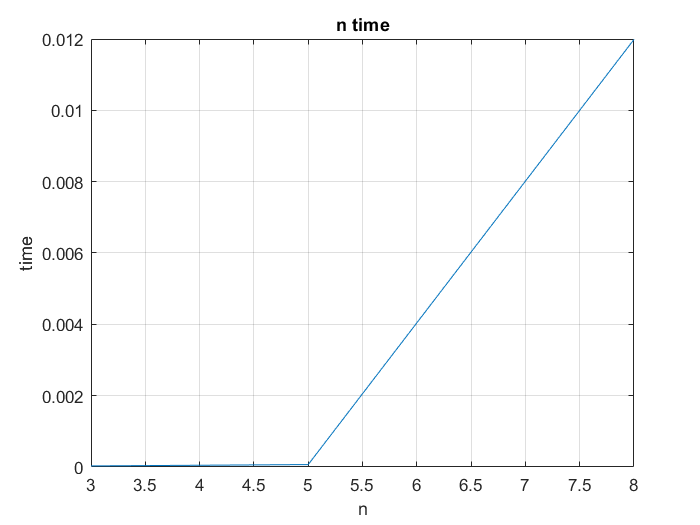

plot(N,T1)
grid on
xlabel('n')
ylabel('time')
title('n time')

## **Find all extreme recession direction in a polyhedra**

N=[3 5 8]; r=@(n)2*n; T2=[]; AllD={};

for n=N
    A=randn([r(n) n]); bi=[1;zeros(n-1,1)]; D=[];
    t1=tic;
    ACWR=nchoosek(1:r(n),n-1); % All Combinations Without Repetition
    dACWR=size(ACWR);
    for i=1:dACWR(1)
        Ai=[ones(1,n);A(ACWR(i,:),:)];
        if det(Ai)~=0
            D=[D,Ai\bi];
        else
            D=[D,ACWR(i,:)'] % Not Solvable
        end
    end
    t2=toc(t1);
    T2=[T2,(t2)/60];
    AllD=[AllD,D];
end

AllD{:} , T2

ans =     0.2716    5.0544   -0.4436    0.0563    0.2334    0.7301    2.1870    0.1798    0.2417    0.2553   -0.7747    0.0871   -0.1910    0.1195    0.2795
    0.3693   -4.7294    1.1318    0.5988    0.4100    0.6443    1.5179    0.3143    0.3514    1.2344    2.5144    1.4433    1.1689    1.2144    0.0844
    0.3591    0.6749    0.3119    0.3449    0.3566   -0.3744   -2.7048    0.5060    0.4069   -0.4897   -0.7396   -0.5305    0.0222   -0.3340    0.6361


ans =     1.0646    0.2950    0.3468    4.5728   -4.6974    5.7477    0.5596    1.2492    0.8682    0.9529    0.9129    0.8433    0.9627    0.3292   -0.5163   -0.3168   -1.3626    0.4449    0.6667    0.7367    0.9245   -0.0875    0.2438    8.2892    0.9962    1.8344    1.1891    1.3454    0.3039    0.5798    0.5816    0.3211    1.9047    0.8102    0.2937    0.3011    0.3037    0.2810    0.2918    0.5790    0.7334   -0.2873    0.1441   -0.5299    5.3291    0.9871   27.7109    1.4582   -0.8647    0.5183
    1.3965    0.4111    0.4774    5.8884   -5.9811    7.3927    0.7499    3.1831   -0.5037    0.3160   -0.0707   -0.7442    0.4107    0.5104   -1.9457   -1.3662   -4.4041    0.8465   -0.1246   -0.2563   -0.6096    1.2945   -0.7756   11.6092    0.3826    0.9001    0.2202    0.0887   -0.5644    0.1466    0.1515   -0.5202    3.5623    0.7408    0.5527   -0.2518   -0.5391    1.9438    0.7597    0.1477   -0.0715    1.3775    0.7651   -1.4462    6.9755    0.7343   29.2840    0.7171    0.8020   

ans = 	1.0e+03 *

    0.0001   -0.0001   -0.0009    0.0001    0.0003   -0.0000   -0.0004    0.0004    0.0000    0.0040    0.0011   -0.0002    0.0001    0.0004   -0.0000    0.0002    0.0011    0.0000    0.0001   -0.0003    0.0001    0.0004   -0.0000    0.0000    0.0011    0.0000   -0.0001    0.0001    0.0002   -0.0000   -0.0007    0.0001    0.0001   -0.0009    0.0000   -0.0004    0.0001    0.0001    0.0001    0.0001   -0.0001    0.0004    0.0002    0.0001    0.0003   -0.0000   -0.0001    0.0000   -0.0000    0.0005
    0.0002    0.0006    0.0027    0.0002   -0.0002    0.0006    0.0013   -0.0004    0.0004   -0.0092   -0.0007    0.0005    0.0002   -0.0000    0.0004    0.0001   -0.0007    0.0003    0.0002    0.0009    0.0004    0.0001    0.0006    0.0005   -0.0007    0.0005    0.0007   -0.0003   -0.0005    0.0002    0.0021   -0.0004   -0.0002    0.0025   -0.0010   -0.0061    0.0003   -0.0003   -0.0005    0.0002   -0.0014   -0.0001   -0.0004   -0.0008   -0.0003    0.0007   -0.0003    0.0012 

T2 =     0.0002    0.0003    0.0111


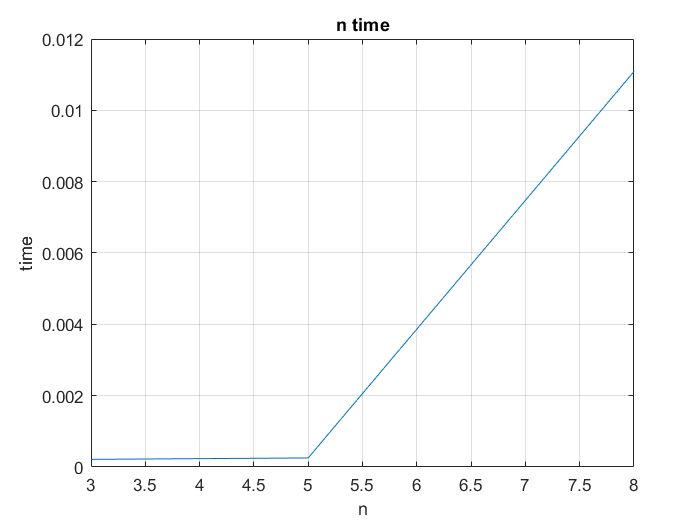

plot(N,T2)
grid on
xlabel('n')
ylabel('time')
title('n time')

## **Find all BFS**

M=[3 5 8]; n=@(m)2*m; T3=[]; AllBFS={};

for m=M
    A=randn([m n(m)]); b=randn(m,1); BFS=[];
    t1=tic;
    ACWR=nchoosek(1:n(m),m); % All Combinations Without Repetition
    dACWR=size(ACWR);
    for i=1:dACWR(1)
        Ai=A(:,ACWR(i,:));
        if det(Ai)~=0
            BFS=[BFS,Ai\b];
        else
            BFS=[BFS,ACWR(i,:)'] % Not Solvable
        end
    end
    t2=toc(t1);
    T3=[T3,(t2)/60];
    AllBFS=[AllBFS,BFS];
end

AllBFS{:} , T3

ans =     0.2191    1.5649    1.0271    0.6418    0.9744    0.7617   17.9808    0.1286    1.1544    0.8985    2.6261    2.8574    2.0608    0.1424    4.4756    6.9565   -0.0713    3.0103    2.3078   -1.3655
    2.0357   -1.5912   -0.9954    1.9873    0.4694    0.3513  -43.8755   -1.1701    0.3889    1.5752    1.2440    1.3599    1.6242   -1.3376   -0.4870   -3.9389   -1.4078    0.4156    1.6581    7.1059
    1.0699    0.7003    2.3643    3.1685    0.3931    1.5878  133.1085    6.3145    1.4089    1.0574   -0.1140   -0.6409   -1.6416    6.8797    5.3717    8.4472    7.2743   -7.6269   -5.8884   -0.1766


ans =    -0.3977   -1.2927   -0.3723   -0.2292    0.3557   -0.3305   -1.0903   -0.1078   -0.9429   -8.1328   -1.7620   -1.0695   -1.0987   -0.9461   -1.0831   -0.7013   -3.9606   -0.6507    3.3872   -0.7395  -15.2894   -0.6277   -0.3460   -0.5663   -0.8976   -0.1570   -0.5100   -0.6641   -0.4099   -0.5225   -0.4211   -0.5576   -0.4726   -2.5346   -0.3876   -0.6074   -1.8528   -2.4208    0.0462   -1.2460   -1.7305    3.6342   -0.7834    0.3696   -1.1484   -3.7712   -1.9612   -0.2483   -0.3251    0.1578
   -0.3876    1.4920   -0.1992   -7.7732   -0.2133   -0.8122    1.0670    1.7611   23.5033   -2.1767    8.2302    1.0818   -0.1984    1.1334    0.9902   17.2137   -0.1294    3.8843   38.9689   27.2943  -13.8672    0.0955   -0.0041    6.9996   -0.5032   -1.9083    0.0539   -3.9847    0.5787   -0.3524    2.3849   -0.1956    1.2714  -37.5704    3.1106   -1.0538    0.5284 -201.3175    1.5905    2.7270   44.0116    3.5973    4.4031   28.1909   19.6700    4.9481  -37.9947    1.4258    6.0634   

ans = 1.0e+04 *

    0.0000    0.0002   -0.0000   -0.0001    0.0002    0.0001   -0.0000   -0.0001    0.0000   -0.0007    0.0001   -0.0000    0.0001    0.0002    0.0000    0.0000    0.0003    0.0038    0.0000    0.0002    0.0001    0.0001    0.0003   -0.0003   -0.0001    0.0001    0.0002   -0.0000   -0.0000    0.0002    0.0004    0.0001   -0.0002   -0.0001   -0.0000    0.0002    0.0003    0.0002    0.0001    0.0001    0.0001    0.0002   -0.0000    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000    0.0000
    0.0002   -0.0001    0.0002   -0.0002   -0.0001    0.0001   -0.0005    0.0005    0.0001    0.0010    0.0000   -0.0000   -0.0001    0.0001   -0.0001    0.0001   -0.0005   -0.0044   -0.0002   -0.0001    0.0002   -0.0003   -0.0002    0.0004   -0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0002   -0.0001    0.0000    0.0002   -0.0001   -0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0000    0.0001    0.0002   -0.0003   -0.0001    0.0000    0.0002    0.0001    0.0002  

T3 =     0.0091    0.0001    0.0059


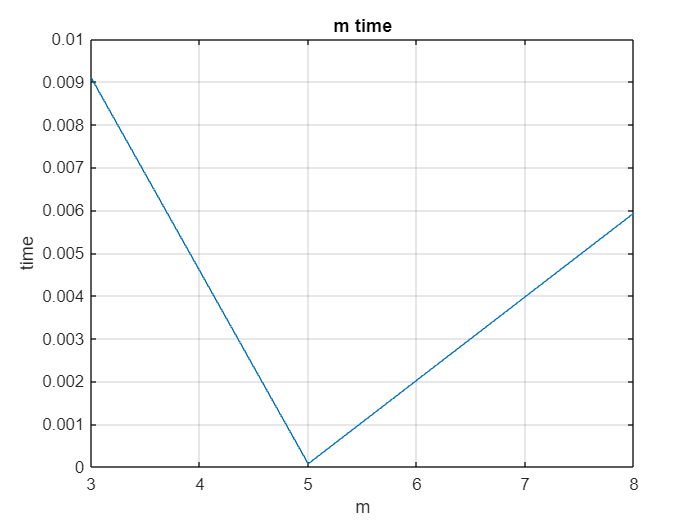

plot(M,T3)
grid on
xlabel('m')
ylabel('time')
title('m time')